# Example: MHKiT-MATLAB Power Module 

This example will demonstrate the MHKiT Power Module functionality to compute power, instantaneous frequency, and harmonics from time series of voltage and current.

We will begin by reading in timeseries data of measured three phase (a,b,and,c) voltage and current. The IEC TS 62600-30 requires that you perform power quality assessments on a minimum of 10-min timseries data, but for this example we will only look at a fraction of that.

% Read in timeseries data of voltage (V) and current (I)
power_table = readtable('../examples/data/2020224_181521_PowRaw.csv');
power_table

power_table = 8000×7 table
           Time_UTC            MODAQ_Va_V    MODAQ_Vb_V    MODAQ_Vc_V    MODAQ_Ia_I    MODAQ_Ib_I    MODAQ_Ic_I
    _______________________    __________    __________    __________    __________    __________    __________

    2020-02-24 18:15:21.499      10653        -8499.4       -1850.2       -23.214         19.22        4.0234  
    2020-02-24 18:15:21.500      10691        -8428.7       -1927.6       -23.405        19.182        4.2899  
    2020-02-24 18:15:21.500      10733          -8365       -2001.3       -23.493        19.034        4.4789  
    2020-02-24 18:15:21.500      10776        -8304.6       -2071.2        -23.68        18.918        4.8582  
    2020-02-24 18:15:21.500      10818        -8248.1         

To use the MHKiT-MATLAB power module we need to create structures of current and voltage. 

current.time = posixtime(power_table.Time_UTC); %setting time in current structure 
voltage.time = posixtime(power_table.Time_UTC); %setting time in voltage structure
T2 = mergevars(power_table,[2 3 4]); %combining the voltage time series into one table variable
T3 = mergevars(T2,[3 4 5]); %combining the current time series into one table variable
current.current = T3.Var3;
voltage.voltage = T3.Var2;


## Power Characteristics 

The MHKiT `power characteristics` submodule can be used to compute basic quantities of interest from voltage and current time series. In this example we will calculate active AC power and instantneous frequency, using the loaded voltage and current timeseries.

To compute the active AC power, we will need the power factor. Power factor describes the efficency of the energy device.

% Set the power factor for the system
power_factor = 0.96 

power_factor = 0.9600

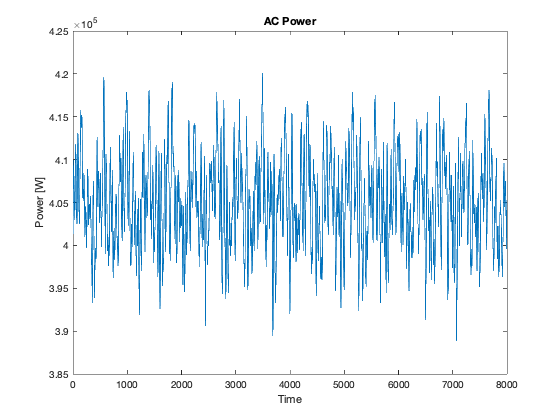


% Compute the instantaneous AC power in watts
ac_power = ac_power_three_phase(voltage, current, power_factor); 
% Display the result
plot(ac_power.time,ac_power.power);
title('AC Power')
ylabel('Power [W]')
xlabel('Time')

### Instantaneous Frequency

Using the 3 phase voltage measurements we can compute the instantaneous frequency of the voltage timeseries. The time-varying instantaneous frequency is a required metric for power quality assessments.

inst_freq = instantaneous_frequency(voltage)

inst_freq = struct with fields:
    frequency: [7999×3 double]
         time: [7999×1 double]


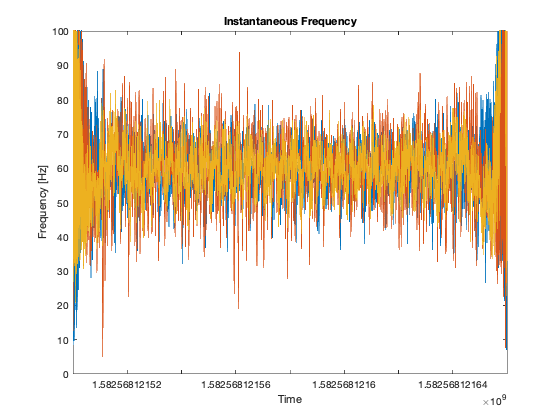

%Display the result
plot(inst_freq.time,inst_freq.frequency);
title('Instantaneous Frequency')
ylabel('Frequency [Hz]')
xlabel('Time')
ylim([0,100])

## Power Quality

The power quality submodule can be used to compute harmonics of current and voltage and current distortions following IEC TS 62600-30 and IEC 61000-4-7. Harmonics and harmonic distortion are required as part of a power quality assessment and characterize the stability of the power being produced.

% Set the sampling frequency of the dataset 
sample_freq = 50000   %[Hz]

sample_freq = 50000


% Set the frequency of the grid the device would be conected to
grid_freq = 60        %[Hz] 

grid_freq = 60


% Set the rated current of the device
rated_current = 18.8  % [Amps]

rated_current = 18.8000

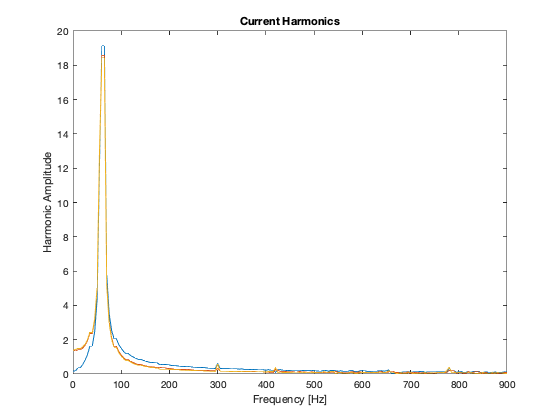


% Calculate the current harmonics
h = harmonics(current, sample_freq, grid_freq);
% display the results 
plot(h.harmonic,h.amplitude);
title('Current Harmonics')
xlabel('Frequency [Hz]')
ylabel('Harmonic Amplitude')
xlim([0,900])

### Harmonic Subgroups

The harmonic subgroups calculations are based on IEC TS 62600-30. We can clculate them using our grid frequency and harmonics.

% Calcualte Harmonic Subgroups
h_s = harmonic_subgroups(h,grid_freq) 

h_s = struct with fields:
    amplitude: [51×3 double]
     harmonic: [0 60 120 180 240 300 360 420 480 540 600 660 720 780 840 900 960 1020 1080 1140 1200 1260 1320 1380 1440 1500 1560 1620 1680 1740 1800 1860 1920 1980 2040 2100 2160 2220 2280 2340 2400 2460 2520 2580 2640 2700 2760 2820 2880 2940 3000]


### Total Harmonic Current Distortion 

Compute the THCD from harmonic subgroups and rated current for the device

% Finally we can compute the total harmonic current distortion as a percentage
% for each channel
THCD = total_harmonic_current_distortion(h_s,rated_current) 

THCD =     8.9725    6.0966    5.9295
